% AE6511 Hw5 Problem 4(c) MATLAB code
% Tomoki Koike 
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');



Iter     Func-count       f(x)      MeshSize     Method
    0           1        72.6385             1      
    1           3        62.9587             2     Successful Poll
    2           9        62.9587             1     Refine Mesh
    3          15        62.4531             2     Successful Poll
    4          21        55.4361             4     Successful Poll
    5          26        55.4361             2     Refine Mesh
    6          33        55.4361             1     Refine Mesh
    7          39         52.349             2     Successful Poll
    8          46         52.349             1     Refine Mesh
    9          51        49.2174             2     Successful Poll
   10          58        49.2174             1     Refine Mesh
   11          65        47.3315             2     Successful Poll
   12          72        47.3315             1     Refine Mesh
   13          79        47.3315           0.5     Refine Mesh
   14          85         37.986             1

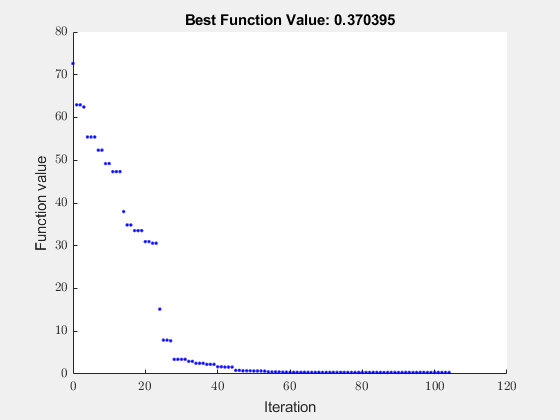

optsol =     0.4620    0.5000    0.5000    6.0717    0.1062    0.1000    0.6938    0.1000


fval = 0.3704

lb = [0.001, -200, -200, 0, 0.1,0.1,0.1,0.1];
ub = [10, 200, 200, 2*pi, 1,1,1,1];
A = [];
b = [];
Aeq = [0,0,0,0,1,1,1,1];
beq = [1];
nonlcon = [];
x0 = [1, 1, 1, 2*pi-pi/3, 0.25, 0.25, 0.25, 0.25];
options = optimoptions('patternsearch','Display','iter', ...
    'PlotFcn',@psplotbestf);
[optsol,fval] = patternsearch(@objfcn,x0,A,b,Aeq,beq,lb,ub,nonlcon,options)

% Check 

tf = optsol(1);
tspan = linspace(0,tf,1000);
init_guess = [-20, 0, optsol(2), optsol(3), optsol(4)];

output = solver(tf,tspan,init_guess);

x_sol     = output.x_sol;
y_sol     = output.y_sol;
theta_sol = output.theta_sol;
xdot_sol  = output.xdot_sol;
ydot_sol  = output.ydot_sol;
lambda1   = output.lambda1;
lambda2   = output.lambda2;
H = output.H;

% Shoreline
x_shore = linspace(min(x_sol),max(x_sol),1000);
y_shore = output.y_shore;

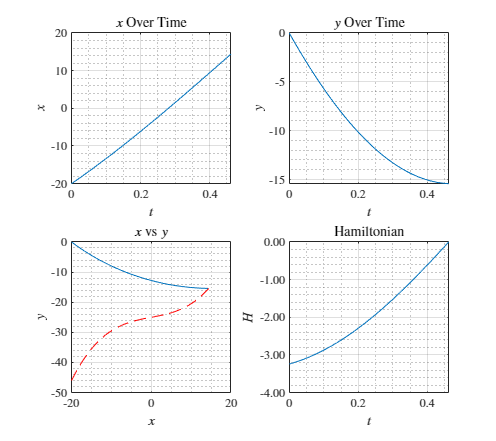

fig = figure("Renderer","painters","Position",[60 60 900 800]);
    % x vs t
    subplot(2,2,1)
    plot(tspan, x_sol)
    title('$x$ Over Time')
    xlabel('$t$')
    ylabel('$x$')
    grid on; grid minor; box on;
    % y vs t
    subplot(2,2,2)
    plot(tspan, y_sol)
    title('$y$ Over Time')
    xlabel('$t$')
    ylabel('$y$')
    grid on; grid minor; box on;
    % x - y 
    subplot(2,2,3)
    plot(x_sol, y_sol)
    hold on;
    plot(x_shore,y_shore, '--r')
    title('$x$ vs $y$')
    xlabel('$x$')
    ylabel('$y$')
    grid on; grid minor; box on; hold off;
    % Hamiltonian 
    subplot(2,2,4)
    plot(tspan, H)
    title('Hamiltonian')
    xlabel('$t$')
    ylabel('$H$')
    ytickformat('%,.2f')
    grid on; grid minor; box on;

% saveas(fig, 'p4c.png');

% Plot control 
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    plot(tspan, theta_sol)
    title('$\theta$ Over Time')
    xlabel('$t$')
    ylabel('$\theta$')
    ytickformat('%,.4f')
    grid on; grid minor; box on;
% saveas(fig, 'p4c_theta.png');

function obj = objfcn(x)
    tf = x(1);
    tspan = linspace(0,tf,1000);
    init_guess = [-20, 0, x(2), x(3), x(4)];
    
    output = solver(tf,tspan,init_guess);
    H = output.H;
    y_sol = output.y_sol;
    y_shore = output.y_shore;
    Hf = (1 + output.lambda1(end) * output.xdot_sol(end) ...
        + output.lambda2(end) * output.ydot_sol(end));
    
    % weights
    w1 = x(5);
    w2 = x(6);
    w3 = x(7);
    w4 = x(8);

    obj = (w1 * abs(y_sol(end) - y_shore(end)) ...
        + w2 * sum(abs(diff(H))) ...
        + w3 * abs(Hf) + w4 * tf);
end

function dxdt = ode(t,x,V)
    dxdt = zeros(5,1); 
    dxdt(1) = V * cos(x(3)) - x(2) + 50; % x
    dxdt(2) = V * sin(x(3)) + 2*x(1) - 30; % y
    dxdt(3) = -2 * x(4); % lambda1
    dxdt(4) = x(3); % lambda2
    dxdt(5) = 2*sin(x(5))^2 + cos(x(5))^2; % theta
end

function output = solver(tf,tspan,init_guess)
    V = 15;
    % ode45
    optslv = optimset('TolX',1e-7,'TolFun',1e-7, ...
        'Display','off','MaxIter',500);
    xout = ode45(@(t,x) ode(t,x,V),[0, tf], init_guess, optslv);
    sol = xout.y'; T = xout.x;
    x_sol = interp1(T,sol(:,1),tspan,'spline'); 
    y_sol = interp1(T,sol(:,2),tspan,'spline');
    theta_sol = interp1(T,sol(:,5),tspan,'spline');
    xdot_sol = V * cos(theta_sol) - y_sol + 50;
    ydot_sol = V * sin(theta_sol) + 2*x_sol - 30;
    lambda1 = interp1(T,sol(:,3),tspan,'spline');
    lambda2 = interp1(T,sol(:,4),tspan,'spline');
    
    H = 1 + lambda1 .* xdot_sol + lambda2 .* ydot_sol;
    
    % Shoreline
    x_shore = linspace(min(x_sol),max(x_sol),1000);
    y_shore = 0.002*x_shore.^3 + 0.25*x_shore - 25;

    output.x_sol = x_sol;
    output.y_sol = y_sol;
    output.theta_sol = theta_sol;
    output.xdot_sol = xdot_sol;
    output.ydot_sol = ydot_sol;
    output.lambda1 = lambda1;
    output.lambda2 = lambda2;
    output.H = H;
    output.y_shore = y_shore;
end